**CENV2006 Soil Mechanics: Topic C: Oedometer Consolidation**

This is an illustration of the 1D consolidation solution using parabolic isochrones.

clear; close all

syms T1 T2
R1 = (4*T1/3)^0.5 % The solution for the advancing isochrone stage

$$R1 = \sqrt{\frac{4\,T_{1}}{3}}$$

R2 = 1-(2/3)*exp(1/4-3*T2) % The solution for the decaying isochrone stage

$$R2 = 1-\frac{2\,{\mathrm{e}}^{\frac{1}{4}-3\,T_{2}}}{3}$$

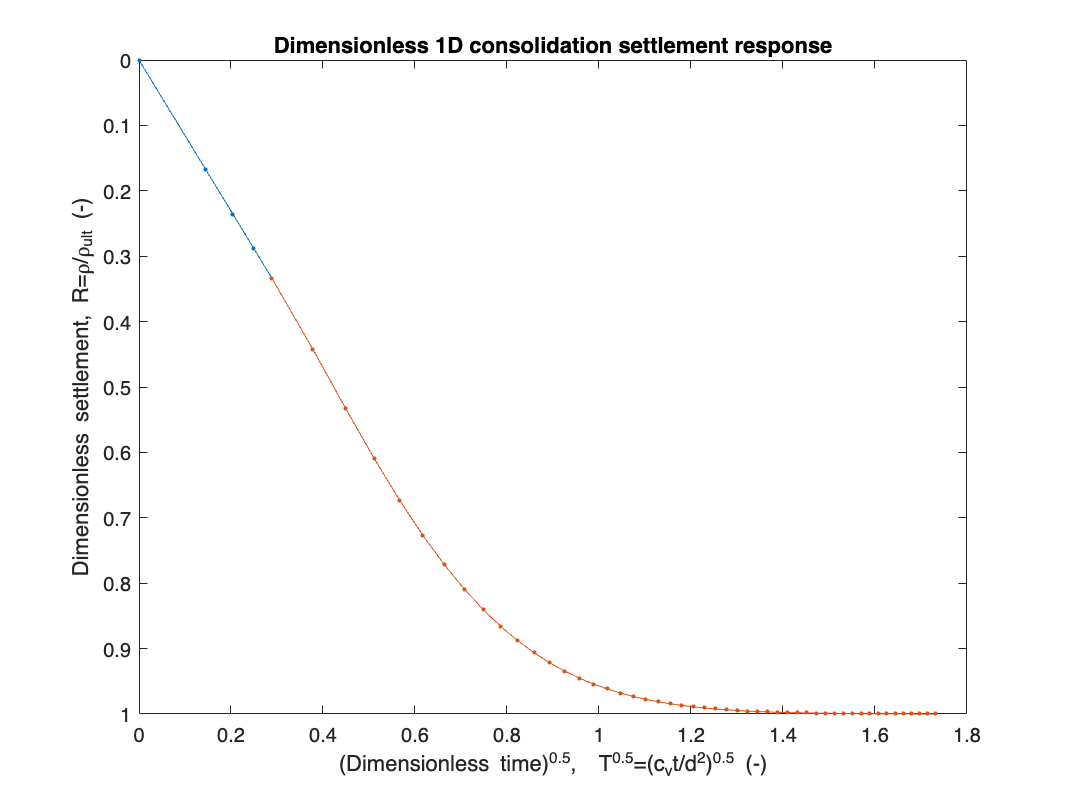

T1 = linspace(0, 1/12, 5); % Setting up a range of values of time for the advancing stage
T2 = linspace(1/12, 3, 50); % Setting up a range of values of time for the decaying stage

plot(sqrt(T1),subs(R1),'.-') % Plot the advancing part of the dimensionless solution
hold on
plot(sqrt(T2),subs(R2),'.-') % Plot the decaying part of the dimensionless solution
axis ij
xlabel('(Dimensionless time)^{0.5},  T^{0.5}=(c_vt/d^2)^{0.5} (-)') % Tidy the plot up
ylabel('Dimensionless settlement, R=\rho/\rho_{ult} (-)')
title('Dimensionless 1D consolidation settlement response')
hold off


T=[T1 T2]; % Assembling a single vector of the dimensionless time values
R=[subs(R1) subs(R2)]; % Assembling a single vector of the corresponding dimensionless settlement values

Now we can plot the response in dimensional form, by inputting the relevant dimensions and properties for our oedometer test. Using these dimensional values, we can set up vectors of time, t, and settlement $\rho$, by calculating from the dimensionless values.

c_v =3.46 ; %mm2/min Consolidation coefficient, cv
c_vSI = c_v/(60*1e6) ; % Additional value of cv given in SI units of m2/s
d_oedo = 10; %mm Drainage distance, i.e. half of the sample thickness
d_sigma = 25; %kPa Increament of stress
rho_ult_oedo = 0.21 ; %mm Slider for the ultimate consolidation settlement
rho_air_oedo = 0.05; %mm Slider for the initial settlement to be discounted as trapped air
E_0 = d_sigma/(rho_ult_oedo/(2*d_oedo)); %kPa Calculation of the Young Modulus, E'0 = stress increment / strain increment

t_oedo=T*d_oedo^2/c_v; % Dimensional time steps
rho=rho_ult_oedo*R; % Dimensional settlement steps
plot(t_oedo.^0.5,rho+rho_air_oedo,'.-') % Generate plot
hold on
axis ij
xlabel('(Time)^{0.5},  t^{0.5} (min^{0.5})') % Tidy the plot up
ylabel('Settlement, \rho (mm)')
title('Oedometer 1D consolidation settlement response')

Lines can also be added to represent the graphical construction for tx 

t_x = 3*d_oedo^2/(4*c_v); % Definition of tx from lecture notes
plot([0 1.05*t_x^0.5],[rho_air_oedo 1.05*rho_ult_oedo+rho_air_oedo],'g-') % Sloping line that extends 5% beyond the intersection point
plot([0 1.5*t_x^0.5],[rho_ult_oedo+rho_air_oedo rho_ult_oedo+rho_air_oedo],'g-') % Ultimate settlement line

Now let's overlay some oedometer data (from question 4.4), which we will fit the theoretical solution to, by adjusting the sliders above.

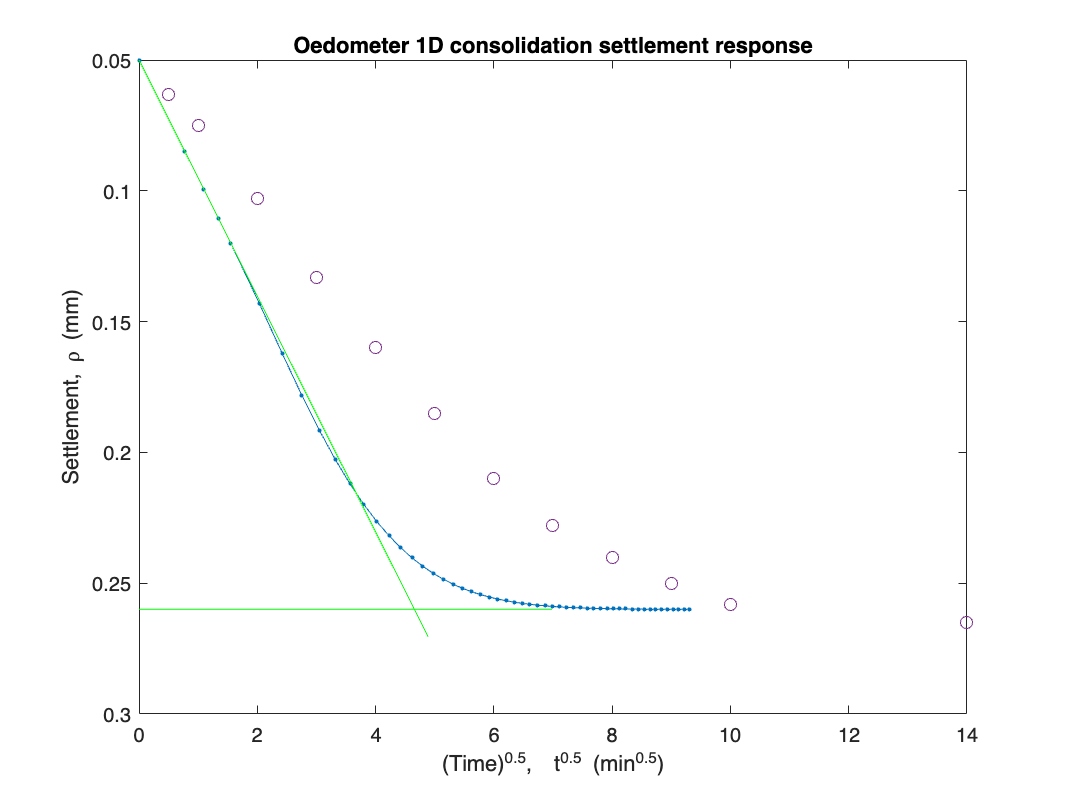

time_oedo = [0.0675 0.125 0.25 0.5 1 2 3 6 10 15];  % min Time
rho_oedo = [0.063 0.075 0.103 0.133 0.160 0.185 0.210 0.228 0.240 0.25 0.258 0.265]; % mm Settlement
plot(time_oedo.^0.5,rho_oedo,'o') % Generate markers on plot
hold off

Now that we have defined some consolidation properties, we can apply them to a field situation. Let's model a layer of soft clay beneath an artificial island, which is subjected to the same stress increment as the oedometer test. The clay layer has varying thickness from 20 m to 40 m, over a lateral distance of 500 m, so we will model 6 cases of varying thickness.

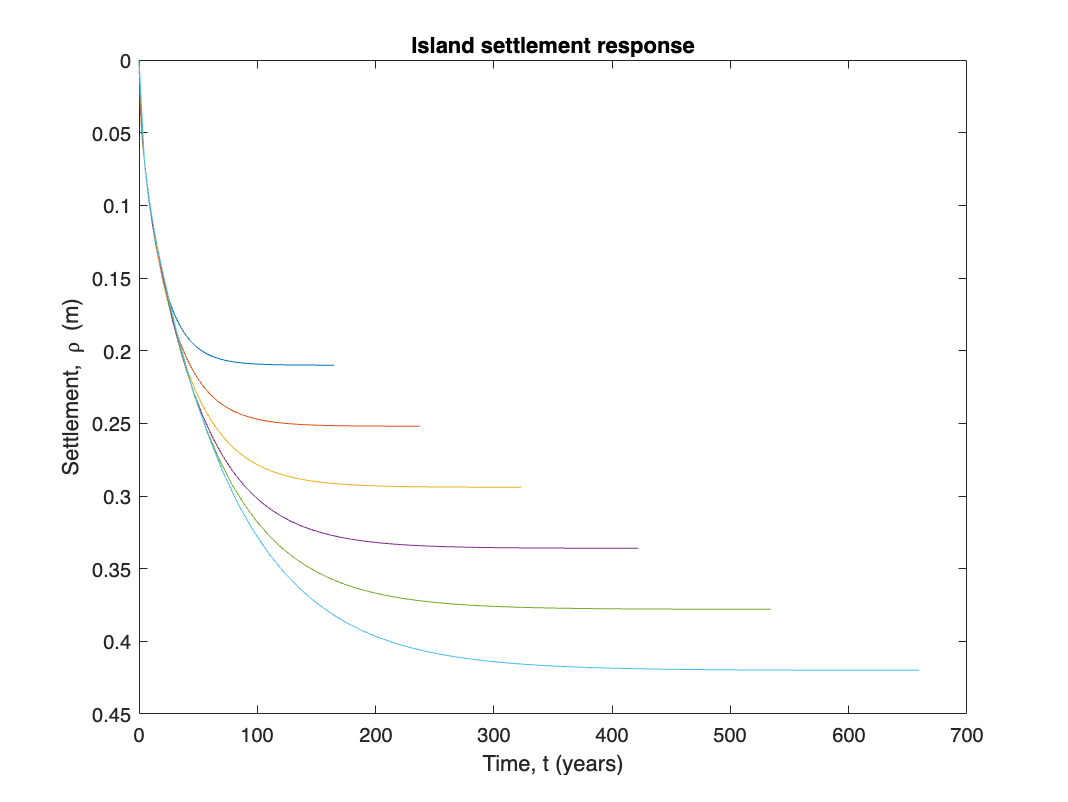

H = (20:4:40); %m Values of sample thickness
X = (0:100:500); %m X-coordinate of each sample thickness case

t_island=(T'*(H/2).^2/c_vSI)/(3600*24*365.25); % Time values, converted from dimensionless into years
rho_ult_island=H*d_sigma/E_0; % Final settlement of island
rho_island=R'*rho_ult_island; % Settlement of island at each time value

plot(t_island,rho_island) % Generate plot
axis ij
xlabel('Time, t (years)')
ylabel('Settlement, \rho (m)')
title('Island settlement response')

It is useful to plot the profile of settlement along the island at a given time. To do this we need to calculate the consolidation of each layer at the same value of time, t, (not the same value of dimensionless T). So let's create a new series of time t, called t_profile. 

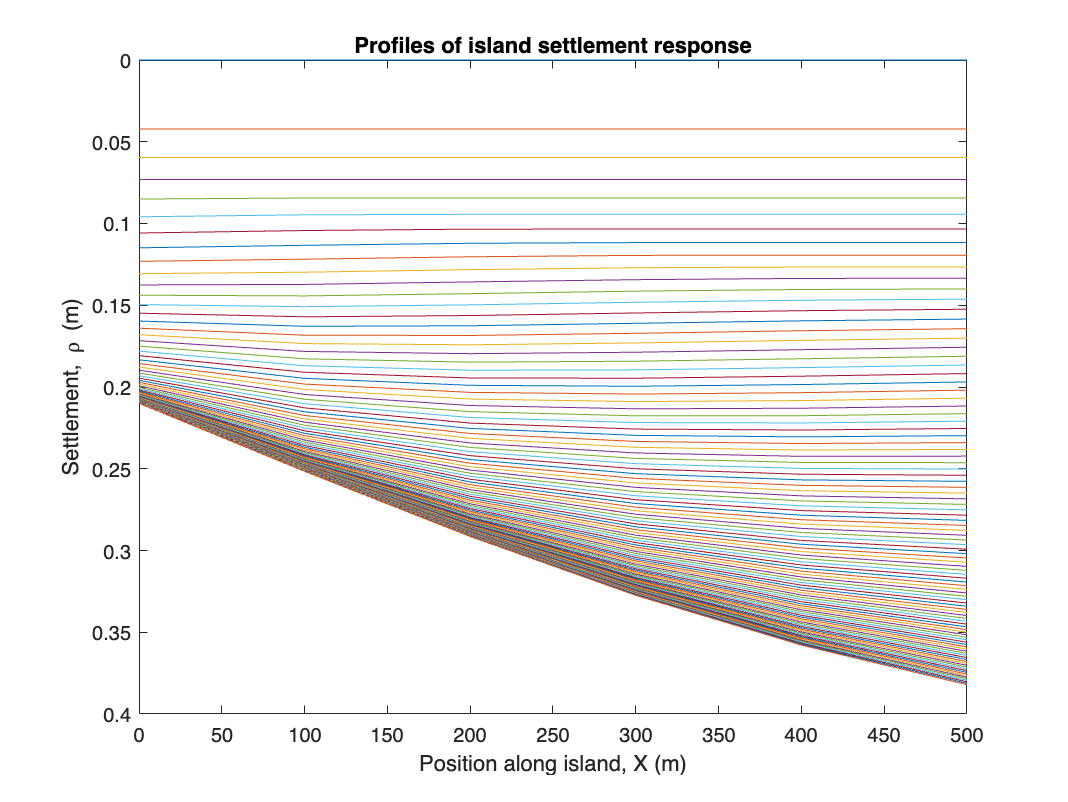

t_profile_max=t_island(end,1)*(3600*24*365.25); % Time series runs to same T as thinnest layer, but in seconds
t_profile=linspace(0,t_profile_max,100); % Values of dimensional time to analyse (100 steps)
T_profile=c_vSI*t_profile'./((H/2).^2); % Corresponding values of dimensionless time to analyse

jmax=size(T_profile,2); % Set up a loop to calculate settlement at each time
R_profile=zeros(100,jmax); % Set up empty matrix of calculated settlement for each X position at each time
for i=1:100
    for j=1:jmax
        if T_profile(i,j)<(1/12)
            R_profile(i,j)=(4*T_profile(i,j)/3)^0.5; % Calculate dimensionless settlement during the isochrone advancing stage
        else
            R_profile(i,j)=1-(2/3)*exp(1/4-3*T_profile(i,j)); % Calculate dimensionless settlement during the isochrone decaying stage
        end
    end
end
rho_ult_island_profile=repmat(rho_ult_island,100,1); % Set up a matrix of the final settlement for each X position
rho_profile=R_profile.*rho_ult_island_profile; % Convert the dimensionless settlement to the dimensional value

figure
for i=1:100
    plot(X,rho_profile(i,:)) % Generate plot of islang profile at each of the 100 time values
    hold on
end
axis ij % Tidy the plot
xlabel('Position along island, X (m)')
ylabel('Settlement, \rho (m)')
title('Profiles of island settlement response')